s = tf('s'); % complex number frequency parameter

## First order system

    % Time constant
    T = 0.05; % [s]
    
    % Gain
    K = 0.5; % [-]
    
    % Transfer function
    G = K / (s*T + 1); % [-]
    
    K_org = K;
    T_org = T;
    p_org = [K_org; T_org];

## System step response

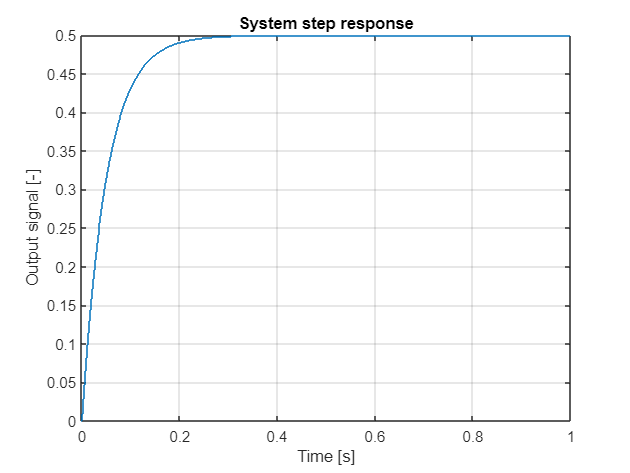

    % Sample time
    ts = 0.001; % [s]
    
    % Time vector
    t = (0 : ts : 1 - ts)'; % [s]
    
    % Input signal: step function
    u = [0; 0.5; ones(length(t)-2,1)];
    
    % Input signal: white noise
    %u = wgn(length(t), 1, 1);
    %u = 10*randn(length(t),1);
    
    % Output signal: system response
    y = lsim(G, u, t);
    
    % Plot result
    stairs(t,y, 'DisplayName', 'System'); grid on; hold on;
    xlabel('Time [s]');
    ylabel('Output signal [-]');
    title('System step response');

## System identification

    data = iddata(y,u,ts);
    
    G_ident = tfest(data, 1);
    [num, den] = tfdata(G_ident);

    K_ident = num{1}(end) / den{1}(end);
    T_ident = den{1}(1) / den{1}(end);
    p_ident = [K_ident; T_ident];

    p_sym = {'K'; 'T'};
    tab = table(p_sym, p_org, p_ident)

tab = 2×3 table
    p_sym    p_org    p_ident 
    _____    _____    ________

    {'K'}     0.5      0.49999
    {'T'}    0.05     0.049942


## System validation

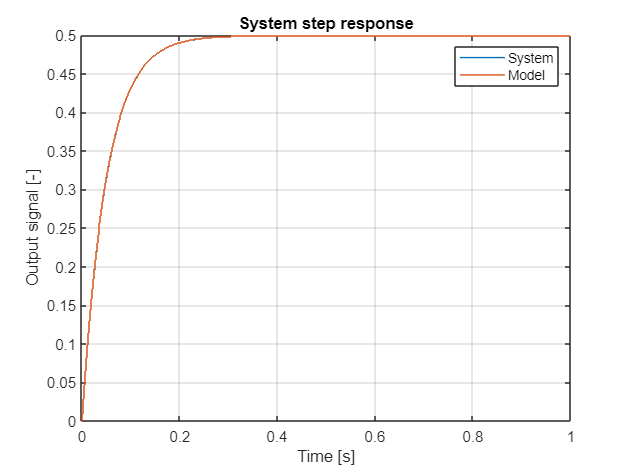

    y_ident = lsim(G_ident, u, t);
    stairs(t,y_ident, 'DisplayName', 'Model');
    legend();